# Actividad 1.2: Parametrización de trayectorias

Víctor Manuel Vázquez Morales A01736352

#### 1. Implementar el código requerido para generar la parametrización de las siguientes trayectorias en un plano 2D: 

Para cada uno de los ejercicios usaremos un periodo de tiempo de -2pi a 2pi.

%Se define el parámetro "t" de parametrización sobre el cual se realizará
%la proyección de trayectoria
t = [-2*pi:0.01:2*pi]; 


**Figura 1: **

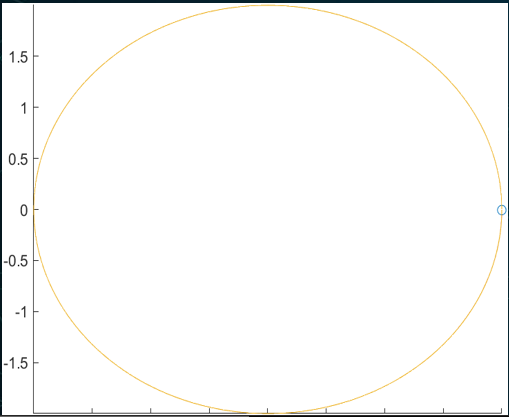

Para este ejercicio, podemos considerar que la figura partió de [2,0] , moviendose hacia la izquierda y regresando para terminar de formar el círculo. Considerando esto, podemos identificar lo siguiente: 

- En el eje x, la trayectoria parte de 2 y, muy probablmente, este se mueve hacia -2 para posteriormente regresar al valor de 2. Este comportamiento se ajusta perfectamente al de un coseno, ya que esta función varia sus valores de 1 a -1. Ahora bien, para lograr que sus valores se ajusten de 2 a -2 debemos multiplicar dicha función por 2:


$$x=2\cos \left(t\right)$$


- En el eje y, podemos identificar de igual forma que los valores                                  varian de -2 a 2, por lo que fácilmente podria tratarse del doble de una función coseno/seno. Ahora bien, considerando que se trata de un círculo y que el eje y es igual a 0 cuando x es igual a 2, podemos decir que se trata de una función seno:  

                                                                
$$y=2\cos \left(t\right)$$
                                                                

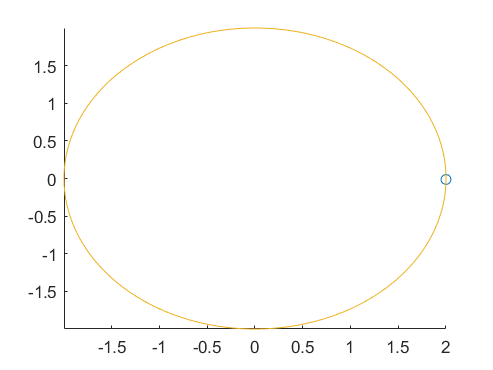

%De definen las funciones en 2D
x1 = 2*cos(t); 
y1 = 2*sin(t); 

comet(x1, y1);

**Figura 2: **

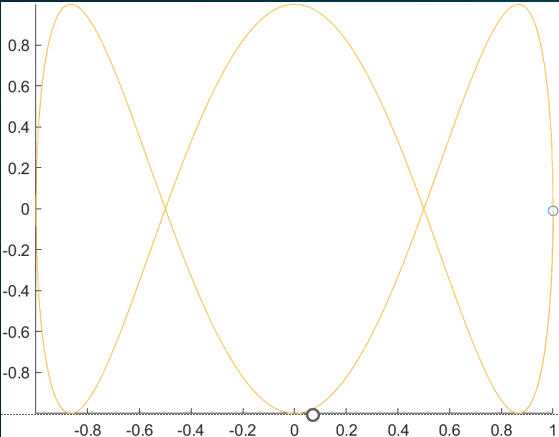

Para este ejercicio, podemos considerar que la figura partió de [1,0] , moviendose hacia la izquierda y regresando para terminar de formar la trayectoria.  Considerando esto, podemos identificar lo siguiente: 

- En el eje x, la trayectoria varia sus valores de 1 a -1, por lo que podriamos considerar que para este eje se trata de una función coseno: 


$$x=\cos \left(t\right)$$


- Para el eje y, podemos observar que la trayectoría parte de 0, variando sus valores de la siguiente forma: 0 $\longrightarrow$ 1$\longrightarrow$ 0 $\longrightarrow$ -1 $\longrightarrow$  0. Este comportamiento se ajusta perfectamente al de una función seno. Ahora bien, observemos que el comportamiento o variación de valores previamente descrito se repite 3 veces. Dicho esto, podemos identificar que la frecuencia de esta función es de 3 y, por lo tanto:  

                                                                
$$y=\sin \left(3*t\right)$$
     

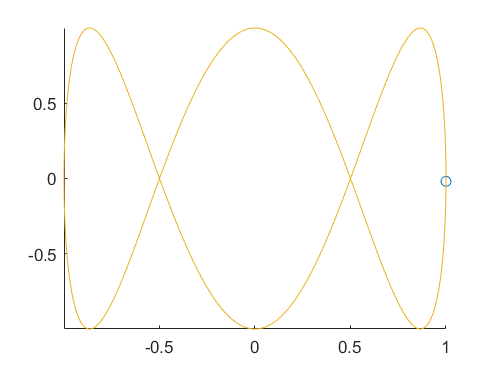

%De definen las funciones en 2D
x2 = cos(t); 
y2 = sin(3*t); 

comet(x2, y2); 

**Figura 3: **

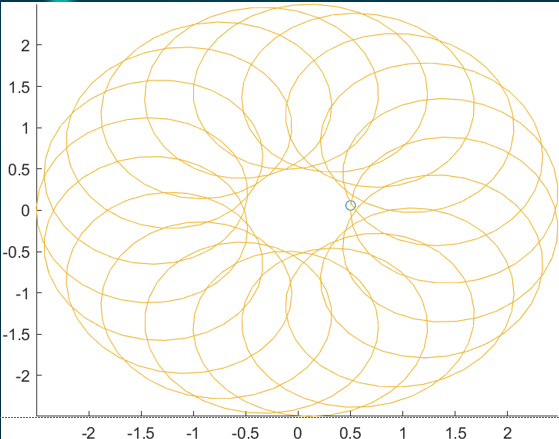

Para lograr una aproximación a la trayectoria de esta fitura, partimos realiznado el siguiente analisis:

- Partiremos del hecho que la figura en general parece tratarse de circulos rotando alrededor del origen. Tomando eso en consideración, partimos definiendo la ecuación como la del primer ejercicio:

  
$$x=\cos \left(t\right)$$



$$y=\sin \;\left(t\right)$$


- Ahora bien, notemos que a la par que se dibujan o trazan estos circulos, tenemos oscilaciones tanto para el eje x como para el eje y, lo que provoca el efecto característico de la trayectoria de la imagen. Para lograr estas "oscilaciones" debemos sumar a nuestras funciones un seno o coseno con una frecuencia alta, por ejemplo: 


$$x=\cos \left(t\right)+\cos \left(20t\right)$$



$$y=\sin \;\left(t\right)+\sin \left(20t\right)$$


- Por último, po rmedio de prueba y error, realizamos algunos ajustes en la amplitud (radio) de los circulos trazados para lograr el efecto de la imagen: un espacio vacio al centro de la figura: 


$$x=1\ldotp 5\cos \left(t\right)+\cos \left(20t\right)$$



$$y=1\ldotp 5\sin \;\left(t\right)+\sin \left(20t\right)$$


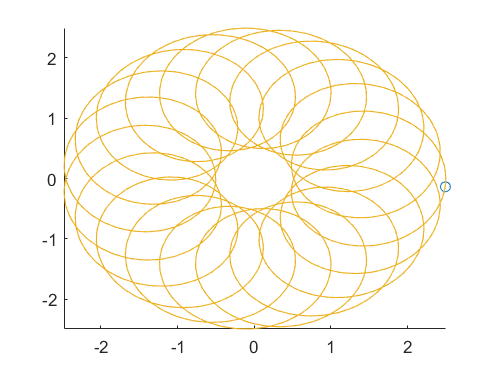

%De definen las funciones en 2D
x3 = 1.5*cos(t)+cos(20*t); 
y3 = 1.5*sin(t)+sin(20*t);

comet(x3, y3); 

**Nota: **A pesar de lograr una muy buen aproximación, debemos resaltar que debemos realizar algunos ajustes  para lograr igualar completamente nuestra trayectoria al de la figura. Sin embargo, nos  hemos acercado considerablemente al resultado deseado. Para ajustar aun mejor la figura podriamos incluso considerar realizar cálculos matemáticos para obtener valores exactos de la función. 

#### **2. Obtener las siguientes trayectorias definidas a partir de curvas paramétricas**

**Inciso a)**

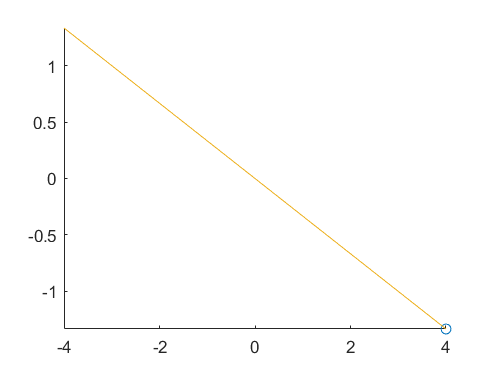

ta = [-2:0.01:2];  %Linespace
xa = 2*ta; 
ya = (ta-3*ta)/3;

comet(xa, ya);

**Inciso b)**

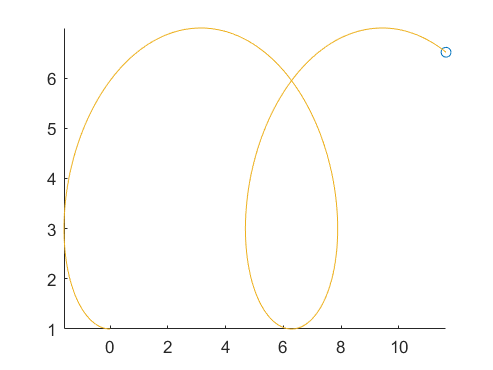

tb = [0: 0.01: 10]; %Linespace
xb = tb-3*sin(tb); 
yb = 4-3*cos(tb);

comet(xb, yb);

**Inciso c)**

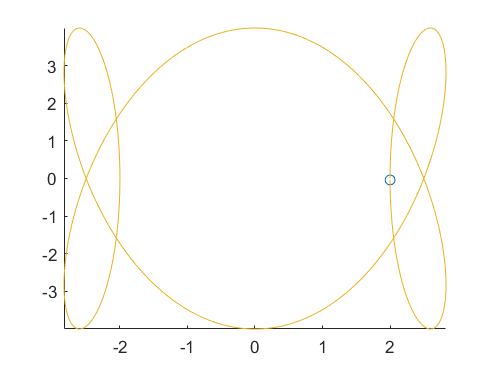

tc = [0:0.01:2*pi]; %Linespace
xc = 3*cos(tc)-cos(3*tc); 
yc = 4*sin(3*tc);
comet(xc, yc);

**Inciso d)**

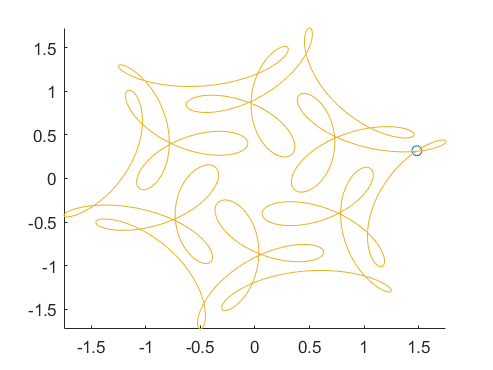

td = [0:0.01:2*pi]; %Linespace
xd = cos(td)+1/2*cos(7*td)+1/3*sin(17*td); 
yd = sin(td)+1/2*sin(7*td)+1/3*cos(17*td);
comet(xd, yd);

**Inciso e)**

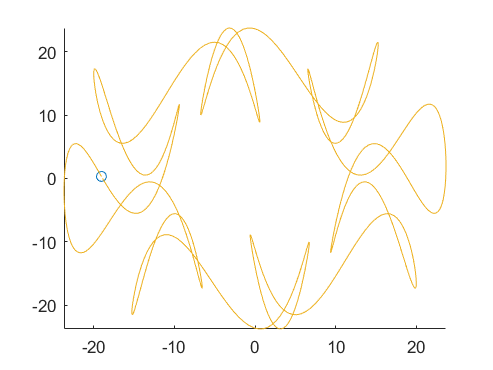

te = [0:0.01:2*pi]; %Linespace
xe = -17*cos(te)+7*cos(17+7*te);  
ye = 17*sin(te)-7*sin(17*te);
comet(xe, ye);

**Inciso f)**

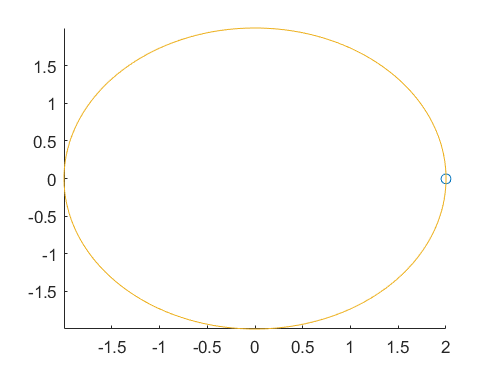

tf = [0:0.01:14*pi]; %Linespace
xf = 2*cos(tf);   
yf = 2*sin(tf); 
comet(xf, yf);

**Inciso g)**

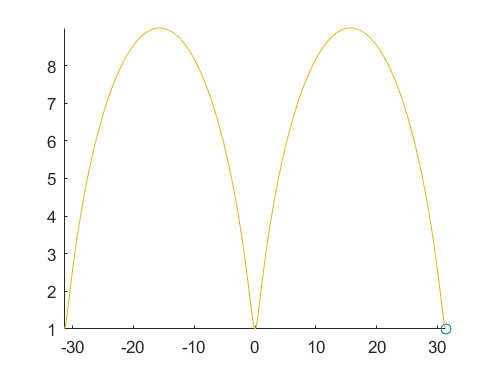

tg = [-2*pi:0.01:2*pi]; %Linespace
xg = 5*tg-4*sin(tg);  
yg = 5-4*cos(tg);
comet(xg, yg);

**Inciso h)**

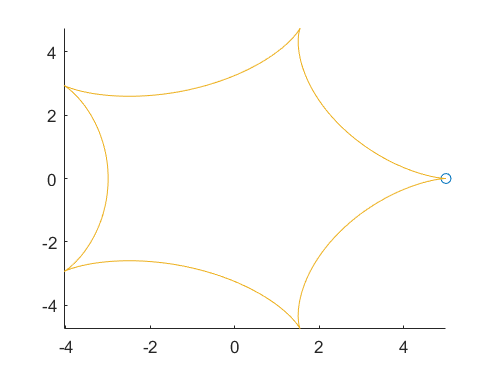

th = [0:0.01:2*pi]; %Linespace
xh = 4*cos(th)+cos(4*th);  
yh = 4*sin(th)-sin(4*th);
comet(xh, yh);

**Inciso i)**

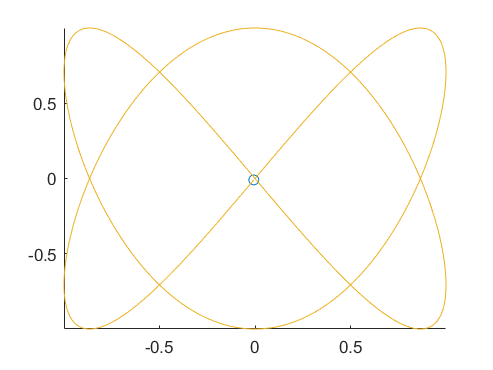

ti = [0:0.01:2*pi]; %Linespace
xi = sin(2*ti);  
yi = sin(3*ti);
comet(xi, yi);

**Inciso j)**

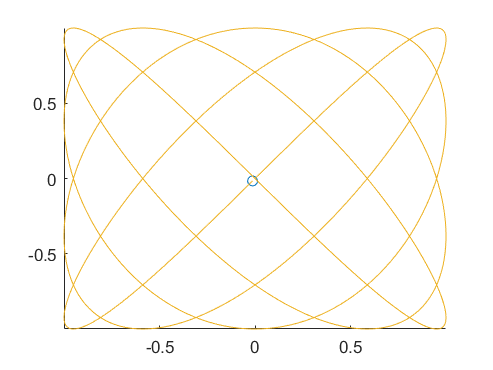

tj = [0:0.01:2*pi]; %Linespace
xj = sin(4*tj);  
yj = sin(5*tj);
comet(xj, yj);